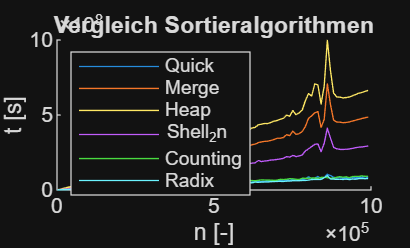

clear;clc;

fid=fopen("quicksort.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
quicksortg_y=data{2};

fid=fopen("mergesort.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
quicksort2_y=data{2};

fid=fopen("heapsort.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
quicksort3_y=data{2};

fid=fopen("shellsort_2n.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
quicksort3_nodebug_y=data{2};

fid=fopen("counting.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
counting_y=data{2};

fid=fopen("radix.txt");
data=textscan(fid,'%d %f');
fclose(fid);
x=data{1};
radix_y=data{2};

figure;
title('Vergleich Sortieralgorithmen');
xlabel('n [-]');
ylabel('t [s]');
hold on;

plot(x, quicksortg_y);
plot(x, quicksort2_y);
plot(x, quicksort3_y);
plot(x, quicksort3_nodebug_y);
plot(x, counting_y);
plot(x, radix_y);
legend('Quick','Merge','Heap','Shell_2n','Counting','Radix', 'Location','northwest');
hold off;

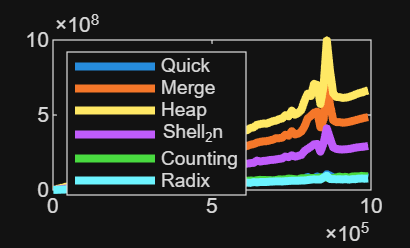


h = plot(x, quicksortg_y,x,quicksort2_y, x, quicksort3_y, x, quicksort3_nodebug_y, x, counting_y,x, radix_y);
set(h,{'LineWidth'},{3})
legend('Quick','Merge','Heap','Shell_2n','Counting','Radix', 'Location','northwest');